# INPUTS

ENTIRE DOCUMENT IS IN RADIANS

format long
inletPressure = 150; %PSIA
outletPressure = 590; %PSIA
mdot = 1.91; %kg/s %%should be 1.91
n = 23000 %RPM

n =        23000


INPUTS FROM ELSEWHERE, CFTURBO

d_H = .023 % determined by key sizing

d_H =    0.023000000000000


beta_2B = 10*pi/180;
beta_1B = 19*pi/180;

ESTIMATED INPUTS THAT LIKELY WON'T CHANGE

i_1 = 0; % for selected incidence angle, degree from 0-4. 0 corresponds to a shockless entry
z_La = 7; %blade number, found based on Gulich's guidelines, Might change after further reading
psi = 1.09; % Assumed head coefficient
f_d1 = 1.15; %table 7.1, for finding inlet diameter
alpha_1 = pi/2; %inlet swirl angle, assumed
eps_sp = 180; %cutwaters of volute at opposite ends of each other
lambda_La = pi/2; % blade inclination angle (????? CORRECT LATER)\
d_w = 0.016; %from calcs on notion

# MAIN DIMENSIONS

DERIVED INPUTS

rho = 804.59; %kg/m^3
pIn = inletPressure * 6894.757;
pOut = outletPressure * 6894.757;
deltap = pOut - pIn

deltap =      3.033693080000000e+06


gravity = 9.81;
H = (pOut-pIn)/(gravity*rho) %Head in meters

H =      3.843509890545300e+02


Q = (mdot)/rho

Q =    0.002373879864279


n_q = ( n * ( sqrt ( Q ) )) / ( H ^ ( 3 / 4 ) )

n_q =   12.909552918934546


P = rho*gravity*H*Q %power at 100% efficiency

P =      7.201622917013634e+03


Q = Q +1.22E-04

Q =    0.002495879864279


eta_V = (mdot/rho)/Q

eta_V =    0.951119442187071


\IMPELLER DIAMETER & BLADE THICKNESS

d_2 = (84.6 / n) * sqrt ( H / psi) % impeller d from assumed

d_2 =    0.069070608096077


u_2 = pi * d_2 * n / 60

u_2 =   83.180157406552553


IMPELLER INLET DIAMETER

d_HStar = d_H/d_2;
d_1Star = .3; %estimate for hub diameter as a ratio of impeller diameter, cancels out later given no-swirl
d_1 = d_1Star * d_2; % this is an estimate but cancels out later. Only matters if swirl angle is nonzero
u_1m = pi * d_1 * n / 60; %inlet circumferential velocity meridional
c_1m = 4 * Q / (d_1^2 - (d_HStar * d_2)^2 ); %absolute velocity meridional
del_r = 1 - c_1m/(u_1m*tan(alpha_1))

del_r =    1.000000000000000


d_1 = d_2 * f_d1 * sqrt ( d_HStar^2 + 0.00148 * psi * n_q ^ ( 4 / 3 ) / ( (eta_V * del_r) ^ .67 ))

d_1 =    0.031911839427332


nu = d_H/d_1; %hub ratio equation from symbols table

IMPELLER OUTLET DIMENSIONS

d_2b = d_2; % true for radial pumps
d_2a = d_2b; % true for radial pumps
d_2i = d_2a; % true for radial pumps
b_2star = .017 + n_q*(.262/100) - .08*((n_q/100)^2) + .0093*((n_q/100)^3) % eq 7.1 with nqref = 100, which comes from fig 7.2 

b_2star =    0.049509784788292


b_2 = b_2star*d_2

b_2 =    0.003419670942033


A_2 = pi*d_2*b_2

A_2 =      7.420402623572272e-04


BLADE AND SHROUD THICKNESSES

e_rec = d_2 * 0.015 * (1 + 0.25*((u_2/100)^2)) * (1 + .5*((n_q/100)^2)) %table 14.3

e_rec =    0.001225396491749


e_rec2min = d_2 * 0.016 % these two are from p.413

e_rec2min =    0.001105129729537


e_rec2max = d_2 * 0.022

e_rec2max =    0.001519553378114


e = 0.002

e =    0.002000000000000


e_1 = e; % constant blade thickness
e_2 = e/2; % trailing edge tapers to half width
e_Rs = e*1.25 %Shroud thicknesses

e_Rs =    0.002500000000000


EFFICIENCIES

%equations from table 3.9
if Q <= 1
    a = 1;
elseif Q > 1 
    a = .5;
end
m = 0.1 * a * ((1/Q)^(.15)) * ((45/n_q)^(0.06));
eta_opt = 1 - (0.095*((1/Q)^m)) - (.3*((.35 - log10(n_q/23))^2)*((1/Q)^(.05)))

eta_opt =    0.389356631160532


m = 0.08 * a * ((1/Q)^(.15)) * ((45/n_q)^(0.06));
eta_Hopt =  1 - (0.055*((1/Q)^m)) - .2*((.26 - log10(n_q/25))^2)*((1/Q)^(.1));
delta_eta = .2*(1-eta_opt)

delta_eta =    0.122128673767894


eta_optmin = eta_opt - delta_eta

eta_optmin =    0.267227957392638


eta_H = eta_Hopt % assumed for now

eta_H =    0.695238896628580


P_max = P/eta_optmin

P_max =      2.694936183803661e+04


FORCES

deltap_La = rho*gravity*H*(1 - (psi/(4*eta_H)))*1.05 %eq 9.2.2 simplified and with correction factor added according to 651 

deltap_La =      1.936863825005171e+06


r_2 = d_2/2;
d_D = d_w; % shaft diameter
d_sp = d_1 + .002 +e_Rs; % increase for shroud and gap

%%rough approximate
f_ax2min = .7* rho * gravity * H * (pi/4) * (d_sp^2 - d_D^2);
f_ax2max = .9* rho * gravity * H * (pi/4) * (d_sp^2 - d_D^2);
f_ax2 = [f_ax2min,f_ax2max] / 1000  % UNITS OF kN %rom table 9.2

f_ax2 =    1.784313278172040   2.294117071935481



%%radial forces from table 9.7
b_2tot = b_2 +2*e_Rs; %total outlet height
F_DSp = 1.75 - 0.0083*(eps_sp);
k_R0 = -5*(10^-5)*(n_q^2) + 9.2*(10^-3)*(n_q)+1.91*(10^-1)

k_R0 =    0.301435059025859


k_RDSp = F_DSp * k_R0

k_RDSp =    0.077167375110620


F_Rst = k_RDSp * rho * gravity * H * d_2 * b_2tot

F_Rst =      1.361425142876483e+02


F_Rdyn = .12 * rho * gravity * H * d_2 * b_2tot %also from table 9.7, using max value for 

F_Rdyn =      2.117099576226151e+02


F_R = F_Rdyn + F_Rst 

F_R =      3.478524719102634e+02


DE HALLER & DEVIATION CRITERIA (CURRENTLY NOT WORKING)

gamma = .98*(1-((sin(beta_2B)^(1/2))/(z_La^0.7)));
tau_2 = (1-((e*z_La)/(pi*d_2*sin(beta_2B)*sin(lambda_La))))^(-1);
c_2m = Q/A_2;
c_2u = u_2 * (c_2m * tau_2/(u_2*tan(beta_2B)));
w_2 = u_2 - c_2u;
u_1 = pi*d_1*n/60;
c_1u = 0; %no inlet swirl
w_1 = ((c_1m)^2+(u_1-c_1u)^2)^(1/2);
w_1a = w_1; %prototype
dec_ratio = w_2/w_1a;
dehaller = dec_ratio >= 0.7

dehaller = logical
   0



%deviation angle checker
c_2u = 48.9

c_2u =   48.899999999999999


c_2m = 3.4

c_2m =    3.400000000000000


beta_2 = 10.6

beta_2 =   10.600000000000000


u_2temp = 67.2

u_2temp =   67.200000000000003



w_2u = u_2temp - c_2u

w_2u =   18.300000000000004


beta_2B = atand(c_2m/w_2u)

beta_2B =   10.525107871028323


del_2 = (beta_2B - beta_2)

del_2 =   -0.074892128971676



phi = c_1m / u_1

phi =   -2.607377502798442


BLADE LOADING

xi_al = (n_q/40)^.77;
xi_eff = xi_al * .9;
w_1star = w_1/u_2;
w_2star = w_2/u_2;
L_starmin = (2*pi*psi)/(eta_H*z_La*xi_eff *(w_1star+w_2star));
L_min = L_starmin * d_2

L_min =    0.134001664338738


syms y x



# MERIDIONAL SECTION

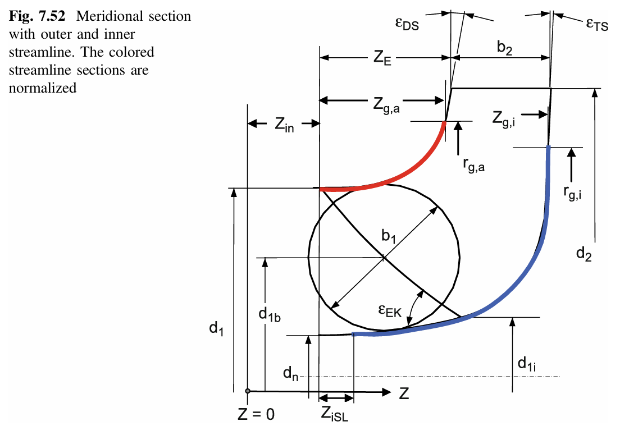

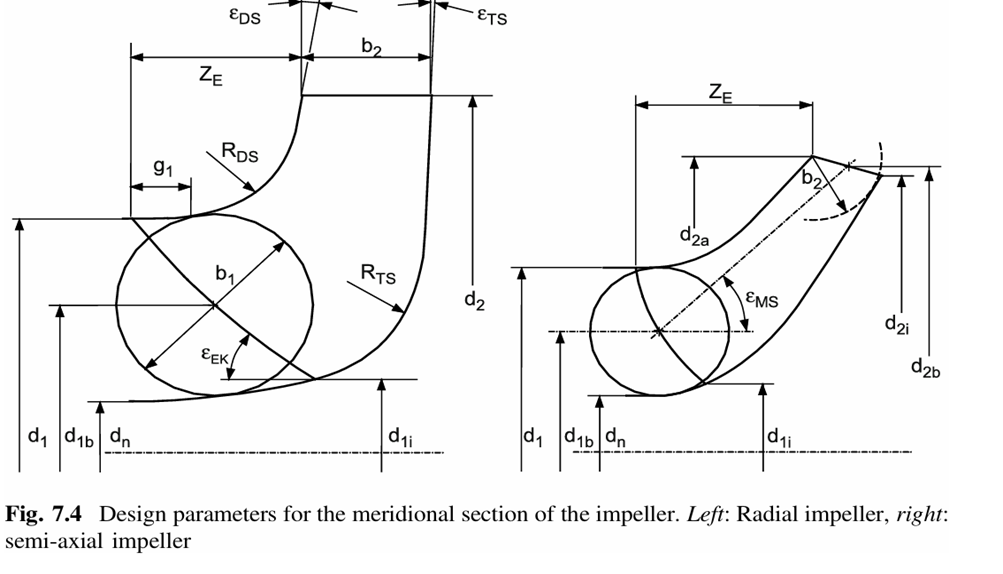

%meridional contour
a = .75

a =    0.750000000000000


x = -0.05

x =   -0.050000000000000


z_E = a*((d_1-d_H)/2)*(n_q/1)^(x) %a*((d_1 - d_H)/2)*(n_q)^(x)

z_E =    0.002940715837183


b_1 = .5*(d_1-d_H)

b_1 =    0.004455919713666


R_DS = .8*(b_1)

R_DS =    0.003564735770933


K_min = 1/R_DS %curvature of top shroud

K_min =      2.805257007136635e+02


g_1 = .2*(b_1)

g_1 =      8.911839427332134e-04


if d_H < .35*d_1
    d_1i = .35*d_1
else
    d_1i = 1.25*d_H
end

d_1i =    0.028750000000000


r_ga = 2.75*(d_1/2)*((1/n_q)^(.16))

r_ga =    0.029141288057951


r_gi = r_ga * .83 * (n_q^.021)

r_gi =    0.025522074466521


eps_ek = 40

eps_ek =     40


eps_Ds = 0;
eps_Ts = 0;
z_iSL = (z_E+b_2)*(.2 + .002*(n_q))

z_iSL =    0.001436296855266


delta_z = z_E + b_2/2

delta_z =    0.004650551308199


# CASING GAPS

# 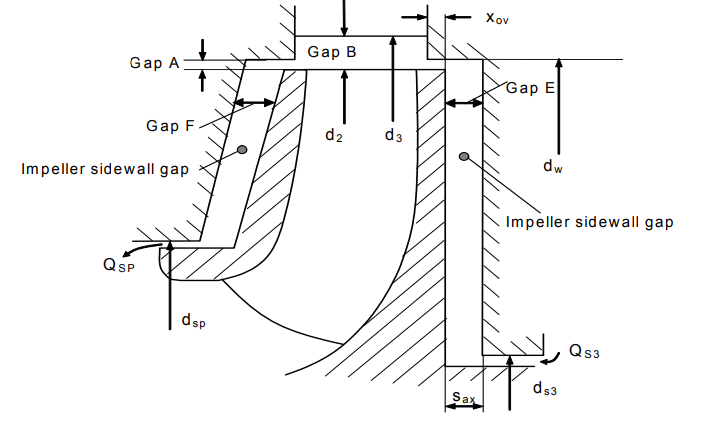

s_ax = d_2*.035

s_ax =    0.002417471283363


d_sp = 2*(.001) + d_1 + 2*(e_Rs)

d_sp =    0.038911839427332


RECALCULATE FORCES

f_ax2min = .7* rho * gravity * H * (pi/4) * (d_sp^2 - d_D^2);
f_ax2max = .9* rho * gravity * H * (pi/4) * (d_sp^2 - d_D^2);
f_ax2 = [f_ax2min,f_ax2max] / 1000  % UNITS OF kN %from table 9.2

f_ax2 =    2.098386633363712   2.697925671467631



%%radial forces from table 9.7
b_2tot = b_2 +2*e_Rs; %total outlet height
F_DSp = 1.75 - 0.0083*(eps_sp);
k_R0 = -5*(10^-5)*(n_q^2) + 9.2*(10^-3)*(n_q)+1.91*(10^-1)

k_R0 =    0.301435059025859


k_RDSp = F_DSp * k_R0

k_RDSp =    0.077167375110620


F_Rst = k_RDSp * rho * gravity * H * d_2 * b_2tot

F_Rst =      1.361425142876483e+02


F_Rdyn = .12 * rho * gravity * H * d_2 * b_2tot %also from table 9.7, using max value for 

F_Rdyn =      2.117099576226151e+02


F_R = F_Rdyn + F_Rst 

F_R =      3.478524719102634e+02


# LEGACY CODE (REPLACED BY CFTURBO OR OBSOLETE)

OUTLET ANGLE

% syms l m o  %l is gamma, m is tau_2, o is beta_2B
% 
% k_w = 1; %test
% eqb1 = H == ( eta_H * (u_2^2) / gravity) * (l - (Q * m / (A_2 * u_2 * tan(o) ) ) );
% eqb2 = l == .98*( 1 - (sqrt( sin( o ) )/(z_La^0.7)  ) );
% eqb3 = m == 1 / ( 1 - ( (e * z_La) / (pi* d_2 * sin(o) *sin(lambda_La) ) ) );
% [gamma,tau_2,beta_2B] = vpasolve(eqb1,eqb2,eqb3,l,m,o)
% 
% clear l m o
% numrots = floor(beta_2B / pi);
% beta_2B = round(beta_2B - (pi*numrots),10)


%%FIRST TRY
% syms d i f g h % d is beta_2B, i is slip factor, f is eps_lim, g is k_w, h is tau_2
% d_1star = d_1 / d_2
% 
% eq1 = f == exp(-(8.16*sind(d))/z_La);
% eq1b = g == 1 - ( ( (d_1star - f) / ( 1 - f ) ) ^3 );
% eq2 = i == .98 * g * ( 1 - ( ( sind(d) ^ (.5) ) / (( z_La )^( .7 )) ) );
% eq3 = H == ((eta_H * (u_2)^2)/gravity) * (i - ( (Q*h) / (A_2*u_2*tand(d)) ));
% eq4 = h == 1/(1 - ((e*z_La)/(pi*d_2*sind(lambda_La)*sind(d))));
% [beta_2B,gamma,eps_lim,k_w,tau_2] = vpasolve(eq1,eq1b,eq2,eq3,eq4,d,i,f,g,h);
% 
% if d_1star <= eps_lim
%     eq1 = f == exp(-(8.16*sind(d))/z_La);
%     eq1b = g == 1;
%     eq2 = i == .98 * ( 1 - ( ((sind(d))^(.5)) / (( z_La )^( .7 )) ) );
%     eq3 = H == ((eta_H * (u_2)^2)/gravity) * (i - ( (Q*h) / (A_2*u_2*tand(d)) ));
%     eq4 = h == 1/(1 - ((e*z_La)/(pi*d_2*sind(lambda_La)*sind(d))));
%     [beta_2B,gamma,eps_lim,k_w,tau_2] = vpasolve(eq1,eq1b,eq2,eq3,eq4,d,i,f,g,h);
% end
% 
% beta_2B = round(beta_2B,10)
% gamma = round(gamma,10)

INLET BLADE ANGLE 

%i_1 = i_1*pi/180;
% 
% syms x y z % x = beta_1B, y = betap_1, z = tau_1
% eq1 = x == y + i_1;
% eq2 = x == atan(c_1m * z / (u_1 - c_1u));
% eq3 = z == 1 / ( 1 - ( (z_La * e_1) / (pi * d_1 * sin(x) * sin(lambda_La) ) ) );
% 
%[beta_1B,betap_1,tau_1] = vpasolve(eq1,eq2,eq3,x,y,z) % these are in radians

VELOCITY TRIANGLE

% %%inlet
% 
% c_1m = 4 * Q / (d_1^2 - d_H^2 ); % meridional component of absolute v
% c_1u = 0; %c_1m / tand(alpha_1); % circumferential component of absolute v, = 0 when no-swirl
% c_1 = sqrt( c_1u^2 + c_1m^2 ) % absolute v
% u_1 = pi * d_1 * n / 60 % circumferential speed
% w_1 = sqrt( c_1m^2 + (u_1 - c_1u)^2 );
% phi = c_1m / u_1; %flow coefficient
% beta_1 = atan( c_1m / ( u_1 - c_1u)  )
% 
% subplot(1,2,1)
% quiver(0,0,u_1,0,'off','r')
% hold on
% quiver(0,0,w_1*cos(beta_1),w_1*sin(beta_1),'off','r')
% quiver(w_1*cos(beta_1),0,0,c_1m,'off','r')
% axis equal
% grid on
% title 'Inlet Velocity Triangle'
% 
% betap_1 = beta_1B - i_1;
% theta = pi - betap_1 - alpha_1; %top angle of the inlet velocity triangle, used for law of sines
% wp_1 = sin(alpha_1) * u_1 / sin(theta)
% cp_1m = sin(betap_1) * u_1 / sin(theta)
% 
% quiver(0,0,u_1,0,'off','--b')
% hold on
% quiver(0,0,wp_1*cos(betap_1),wp_1*sin(betap_1),'off','b')
% quiver(u_1,0,0,cp_1m,'off','--b')
% axis equal
% 
% %%outlet
% subplot(1,2,2)
% title 'Outlet Velocity Triangle'
u_2 = pi * d_2 * (n/60)

u_2 =   83.180157406552553
